# Compressor Map

This example shows how to create the pressure ratio, corrected mass flow rate, and efficiency tables required to specify the performance characteristics of a dynamic compressor.

 
open_system('CompressorMap')

## The Compressor Map

These compressor maps are M x N matrices with the number of rows, M, equal to the number of corrected speeds and the number of columns, N, equal to the number of points along each corrected speed line.  The indexing vectors for these M x N matrices are therefore a corrected speed vector of length M and a vector for an auxiliary coordinate system parameter β of length N with values ranging from 0 to 1.

An example compressor map is shown in the figure below.

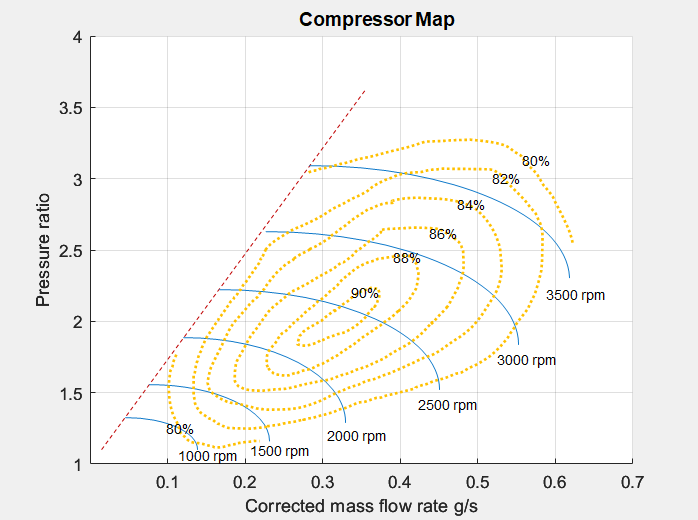

The information contained in this map image must be converted into numerical values and properly organized for use in the Simscape(TM) compressor block.  The easiest way to do this is using a tool such as [GRABIT](https://www.mathworks.com/matlabcentral/fileexchange/7173-grabit) from the MathWorks File Exchange.

With the tool in hand, the next step is to extract the data.

## Extracting Compressor Map Data

The compressor map data must be properly organized when obtained using the GRABIT tool.  The data will be pulled in two separate tasks:

- The compressor corrected mass flow rate and pressure ratio data will be extracted together by picking points along each constant-speed line.

- The compressor efficiency data will be gathered by taking points for each efficiency level.  This data will be a collection of corrected mass flow rate and pressure ratio points valid for a given efficiency.  This data will then need to be interpolated to be consistent with the data gathered in task 1.  

Note: It is important that for each constant speed line the same number of points are picked.  It is also important that for each efficiency level the same number of points are picked.  This is due to the need to organize these sets of data in rectangular matrices without empty entries.

### Flow and Pressure Ratio Values From Constant-Speed Lines

Using the GRABIT tool, load the compressor map image and identify the axes scaling.  For each constant-speed line, pick a consistent number of points and save them each to a MAT file.  The points should be counter-clockwise along each speed line, starting at the choke line (if applicable) and ending on the surge line (shown dashed in red).  See an example below for the points taken at 2500 rpm.

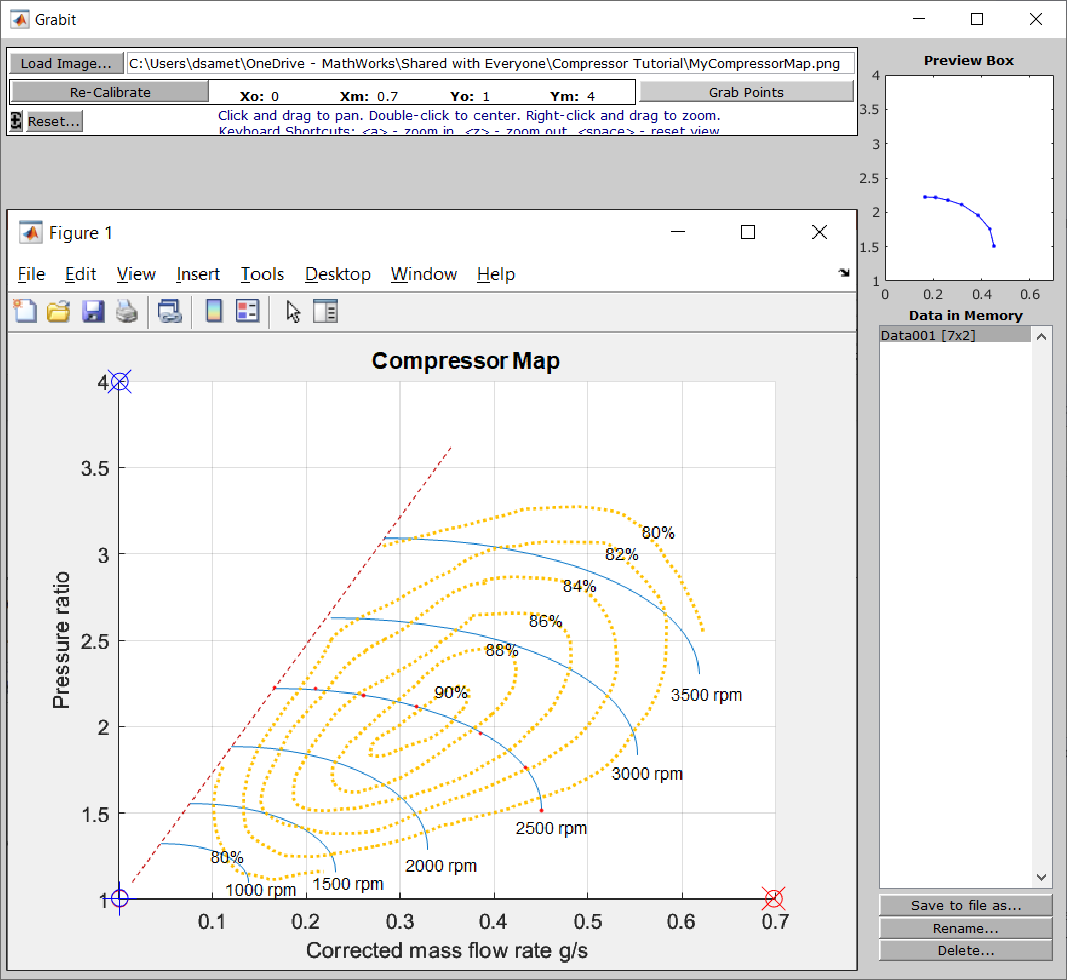

It is preferable to space the selected points as uniformly as possible.  The more regular the resulting grid of flow and pressure ratio points within the defined map space, the more smoothly interpolations of the map, both for defining efficiency and for in use with the Simscape compressor will be.  Do this for all constant-speed lines you wish to be part of the compressor map.

### Efficiency Contours

Again, using the GRABIT tool, now create MAT files containing the corrected mass flow rate and pressure ratio data for each efficiency contour level.  It does not matter in which order the points are selected, or where the selection starts, but again, choosing a direction (clockwise or counter-clockwise) and sticking with it is preferable.  Below, the selection of the 80% efficiency contour can be seen.  It is acceptable that there are "breaks" in the contour lines, but ensure all contour points are selected.  Do not add fictitious points here. 

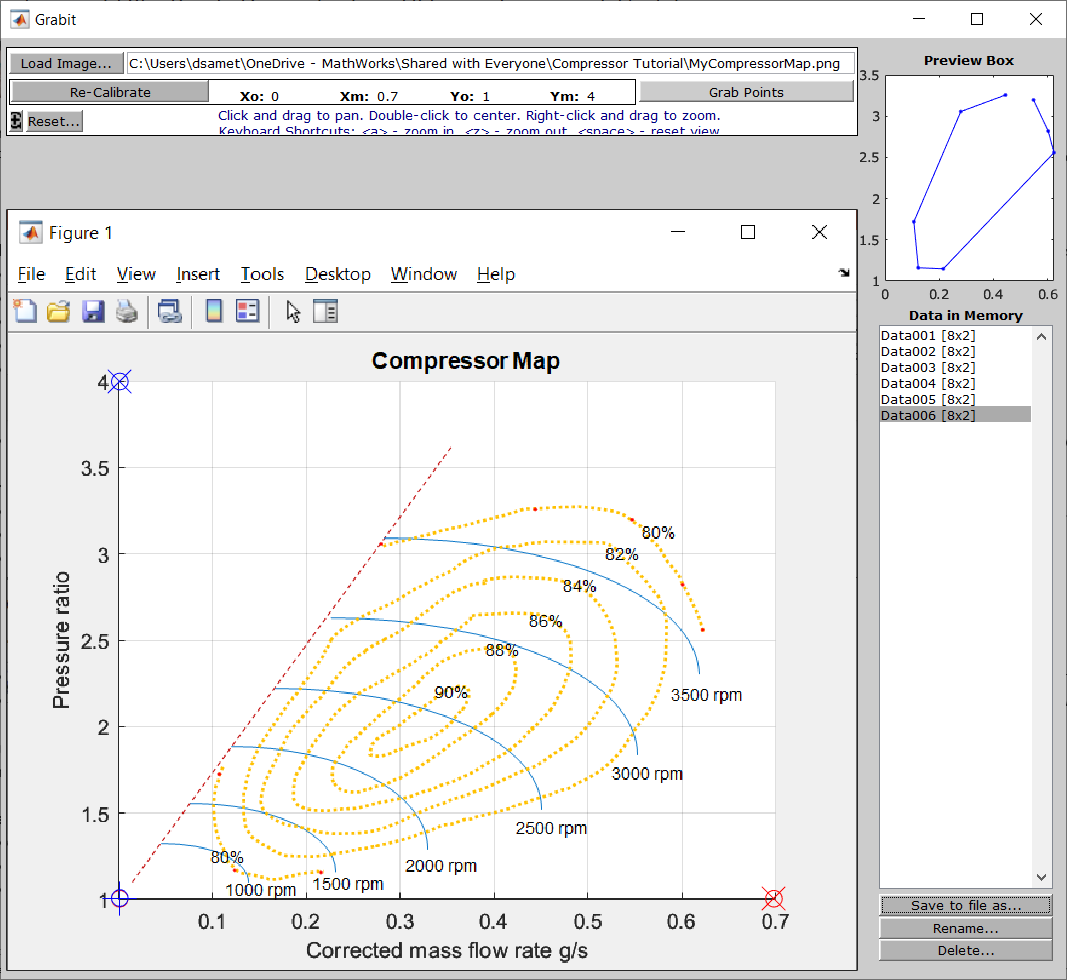

Save your data for both collections of information.  This example assumes the data is saved to MAT files with the naming convention of LineNNNN.mat and EffXX.mat where NNNN and XX refer to the constant-speed line rpm value and the efficiency percentage, respectively.  These MAT files are then combined into single files for the speed lines and efficiency data as shown below for convenience.

## Loading the Data

The data can now be loaded for use in creating the compressor map.  Note: the MAT files used here contain all seven of the MAT files used for the speed lines and all six MAT files for the efficiency contours.

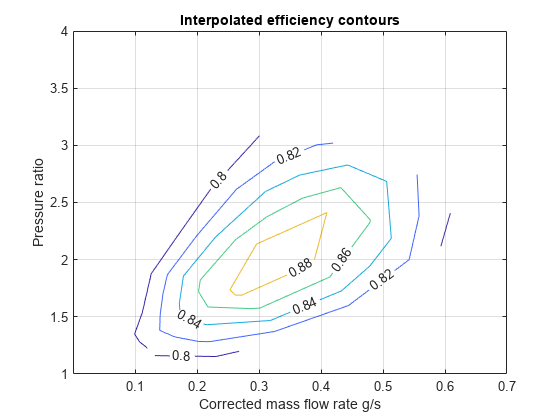

% Load constant speed line data
load('CompressorMapSpeedLines.mat')

% Create matricies for corrected mass flow rate and pressure ratios
mdot_TLU = [Line1000(:,1)'; Line1500(:,1)'; Line2000(:,1)'; Line2500(:,1)'; Line3000(:,1)'; Line3500(:,1)'];
pr_TLU   = [Line1000(:,2)'; Line1500(:,2)'; Line2000(:,2)'; Line2500(:,2)'; Line3000(:,2)'; Line3500(:,2)'];

% Create corrected speed and beta index vectors - must be the dimensions of MDOT_TLU and PR_TLU above

% Values taken from the constant speed lines
omega_TLU = [1000, 1500, 2000, 2500, 3000, 3500];

% Beta ranges from 0 to 1. Length = number of points taken along each constant speed line 
beta_TLU  = linspace(0,1,7);

% Load efficiency data
load('CompressorMapEfficiencyData.mat')

% Organize efficiency data for use in scatteredInterpolant
Efficiency80 = [Eff80, 0.80 .* ones(length(Eff80),1)];
Efficiency82 = [Eff82, 0.82 .* ones(length(Eff82),1)];
Efficiency84 = [Eff84, 0.84 .* ones(length(Eff84),1)];
Efficiency86 = [Eff86, 0.86 .* ones(length(Eff86),1)];
Efficiency88 = [Eff88, 0.88 .* ones(length(Eff88),1)];
Efficiency90 = [Eff90, 0.90 .* ones(length(Eff90),1)];

Efficiency = [Efficiency80; Efficiency82; Efficiency84; Efficiency86; Efficiency88; Efficiency90];

% Interpolate efficiency data onto the corrected mass flow rate and
% pressure ratio locations - this allows the same corrected speed and beta
% values to be used for all three tables

F = scatteredInterpolant(Efficiency(:,1), Efficiency(:,2), Efficiency(:,3), 'linear', 'linear');

eta_TLU = F(mdot_TLU, pr_TLU);

figure
[C, h] = contour(mdot_TLU, pr_TLU, eta_TLU, 0.80:0.02:0.9);
clabel(C, h, 'LabelSpacing', 350)
h.DisplayName = 'Isentropic Efficiency';
title('Interpolated efficiency contours')
xlabel('Corrected mass flow rate g/s')
ylabel('Pressure ratio')
axis([0 0.7 1 4])
xticks([0.1 0.2 0.3 0.4 0.5 0.6 0.7])
yticks([1 1.5 2 2.5 3 3.5 4])
grid on

As seen in the contour plot, the interpolated efficiency contours are qualitatively the same as our source data, and now in a format useful to our compressor block.  If you obtain a compressor map with oversimplified contours missing key details from your map, you need to re-select your data using a denser mesh.  This may involve any combination of taking more points along each speed line, taking points along estimated newly created additional speed lines, or more data points for each efficiency contour level.  It may be noted that this process inherently involves interpolation of data which may result in some precision loss.  The only way to avoid this is to obtain the original raw test data used to generate the maps in the first place.  Such data should a complete collection of corrected mass flow rates, pressure ratios and efficiency values at a variety of operating conditions and speeds.  This data, and the data used by the compressor block, is specified in the auxiliary coordinate system defined by the corrected speed, and the auxiliary coordinate β.

## Implementation of Compressor Maps in Simscape

With the compressor maps now contained in the workspace variables below, they are available for use in the simscape compressor block.

- omega_TLU

- beta_TLU

- pr_TLU

- mdot_TLU

- eta_TLU

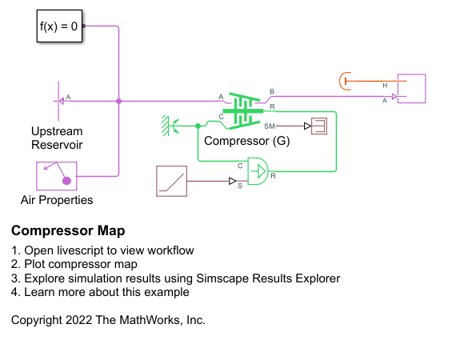

For this model, the compressor reference temperature and reference pressure have been set to the inlet reservoir temperature and atmospheric pressure.  In doing so, the corrected mass flow rate and corrected speed values used by the compressor will be the same as the uncorrected values used in places like the ideal angular velocity source, since the correction factor will be equal to one.  This model is set to increase the pressure in a constant volume chamber by ramping up the compressor commanded speed.

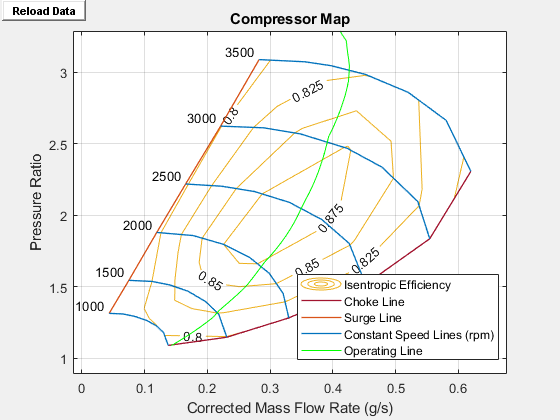

 % Simulating model
sim('CompressorMap')

% Since Pressure and Temperature at A are at reference, mdot_A = mdot_corrected in grams/s
mdot_corrected = simlogCompressorMap.Compressor_G.mdot_A.series.values('g/s');

% Pressure Ratio
PR = simlogCompressorMap.Compressor_G.B.p.series.values ./ simlogCompressorMap.Compressor_G.A.p.series.values;

% The code below plots the compressor map using the same function as the
% simscape block available by right clicking on the block and selecting
% Fluid > Plot Compressor Map
handle = getSimulinkBlockHandle('CompressorMap/Compressor (G)');
fluids.internal.mask.plotCompressorMap(handle)
hold on
% Plot operating line of compressor transient
plot(mdot_corrected, PR,'g','DisplayName','Operating Line')

As seen, the compressor map displayed from the Simscape block compares favorably to the original source map.  Some interpolation error will occur, but the impact can be minimized with good point selection practices.

Copyright 2022 The MathWorks, Inc.